%{
Name: Solar Bill Equations
Author: Evan Scheuritzel
Version: 1.1
Purpose:
Input:
Output:
%}

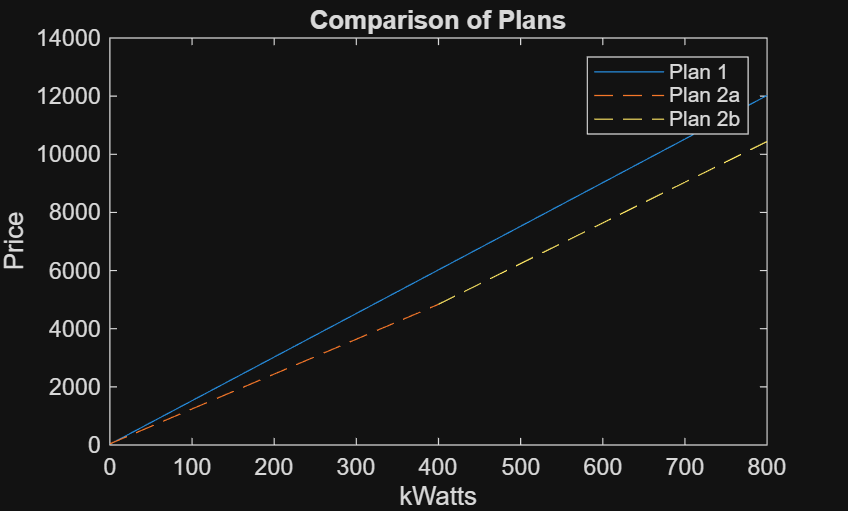


clear
x = 0:25:800;
xa = 0:25:400;
xb = 400:25:800;
plan1 = 15*x+25;
plan2a = 12*x+40;
plan2b = 14*x - 760;
plot(x,plan1)
hold("on")
plot(xa, plan2a(1:numel(xa)), '--', xb, plan2b(end-numel(xb)+1:end), '--')
hold("on")

legend('Plan 1', 'Plan 2a', 'Plan 2b');
xlabel('kWatts');
ylabel('Price');
title('Comparison of Plans');


priceTable = table(x', plan1', arrayfun(@priceEqation, x)', 'VariableNames', {'kWatts','Plan1','Plan2'});

disp(priceTable)

    kWatts    Plan1    Plan2
    ______    _____    _____

       0         25       40
      25        400      340
      50        775      640
      75       1150      940
     100       1525     1240
     125       1900     1540
     150       2275     1840
     175       2650     2140
     200       3025     2440
     225       3400     2740
     250       3775     3040
     275       4150     3340
     300       4525     3640
     325       4900     3940
     350       5275     4240
     375       5650     4540
     400       6025     4840
     425       6400     5190
     450       6775     5540
     475       7150     5890
     500       7525     6240
     525       7900     6590
     550       8275     6940
     575       8650     7290
     600       9025     7640
     625       9400     7990
     650       9775     8340
     675      10150     8690
     700      10525     904


function bill = priceEqation(w);
    if w<400
        bill = 12*w+40;
    else
        bill = 14*w - 760;
    end
end